**Q3. Using data set 2 and assuming a one-year investment horizon, no borrowing, and no short sales, investigate the optimal portfolio weights for a portfolio of the four stocks and a single risk-free asset (use any sensible values for the coefficient of risk aversion and risk-free rate).**

%Task 3
%Setting default directory
cd('Set location of your default directory');

% Setting location of the folder where the files are present
file_location = 'Your file location\Matlab assignment\Data set 2';
[stock_price(:,1),~] = log_pop(file_location, 'CAT.xlsx','CAT', 'F2:F146');

%Since the dates for the other dataset will be the same, so not fetching the dates
[stock_price(:,2),~] = log_pop(file_location, 'JPM.xlsx','JPM', 'F2:F146');
[stock_price(:,3),~] = log_pop(file_location, 'NVDA.xlsx','NVDA', 'F2:F146');
[stock_price(:,4),~] = log_pop(file_location, 'WMT.xlsx','WMT', 'F2:F146');


% Calculating monthly returns for all the 4 stocks
return_price = stock_price(2:end,:)-stock_price(1:end-1,:);

% For 1 year investment horizon, need to calculate yearly expected return
% and variances
% Since log returns are used we just need to multiply monthly returns by 12
asset_mean = 12.*mean(return_price);
asset_covar = 12.*cov(return_price);

% Saving the mean, variance and covariance in an excel format
% writematrix(asset_mean,"Task 3 asset mean.xlsx"); %Table 4.1(Uncomment to save)
% writematrix(asset_covar,"Task 3 asset covariance.xlsx"); %Table 4.2(Uncomment to save)

% Creating a empty Portfolio object for mean-variance portfolio optimization
port = Portfolio;

% Setting number of portfolios
num_port = 10;

% Setting estimated moments in port object
port = setAssetMoments(port,asset_mean,asset_covar);

% Setting the constraints to the default values.
port = setDefaultConstraints(port);

% Estimating the efficient frontier weights.
port_wts = estimateFrontier(port, num_port);


% Retrieving the risk and return values.
[port_risk,port_ret] = estimatePortMoments(port,port_wts);

%Collecting the portfolio weights, associated risk and return in one table(array)
% Creating header for the table
Port_head(1,1) = "CAT"; Port_head(1,2) = "JPM";
Port_head(1,3) = "NVDA"; Port_head(1,4) = "WMT";
Port_head(1,5) = "Portfolio Return"; Port_head(1,6) = "Standard Deviation";
Port_weights = port_wts';
Port_weights(:,5) = port_ret;
Port_weights(:,6) = port_risk;
% Concatenating Header and the values
Final_table = vertcat(Port_head,Port_weights);

% Saving the Final_table in an excel format
% writematrix(Final_table,"Task 3 portfolio weights.xlsx"); %Table 4.3(Uncomment to save)

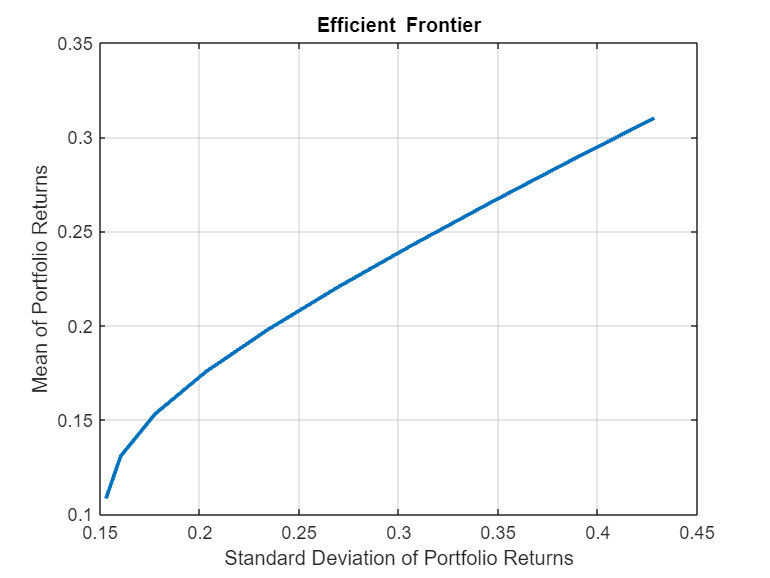

% Plotting the frontier line
plotFrontier(port,num_port);

% Saving the current graph
% saveas(gcf,"fig31.jpg"); % Uncomment to save the graph

% Defining the risk-free rate.
rf_rate = 0.07;

% Setting the rate for borrowing.
br = NaN;

% Setting the risk aversion.
ra = 6;

% Computing the results for optimal final portfolio.
[orp_risk,orp_ret,orp_wts,orp_fraction,ofp_risk,ofp_ret]...
    = portalloc(port_risk,port_ret,port_wts',rf_rate,br,ra);

% Collecting the optimal risky portfolio's risk and return in an array
orp(1,1) = "CAT"; orp(1,2) = "JPM";
orp(1,3) = "NVDA"; orp(1,4) = "WMT";
orp(1,5) = "Expected Return"; orp(1,6) = "Risk";
orp(2,1) = orp_wts(1,1); orp(2,2) = orp_wts(1,2);
orp(2,3) = orp_wts(1,3); orp(2,4) = orp_wts(1,4);
orp(2,5) = orp_ret; orp(2,6) = orp_risk;

% Collecting the optimal final portfolio's risk and return
% and weightage of ORP in an array.
ofp(1,1) = "Expected Return"; ofp(1,2) = "Risk";
ofp(1,3) = "Weightage of Risky Portfolio";
ofp(2,1) = ofp_ret; ofp(2,2) = ofp_risk;
ofp(2,3) = orp_fraction;

% Saving the ORP and OFP in an excel format
% writematrix(orp,"Task 3 orp.xlsx"); %Table 4.4(Uncomment to save)
% writematrix(ofp,"Task 3 ofp.xlsx"); %Table 4.5(Uncomment to save)

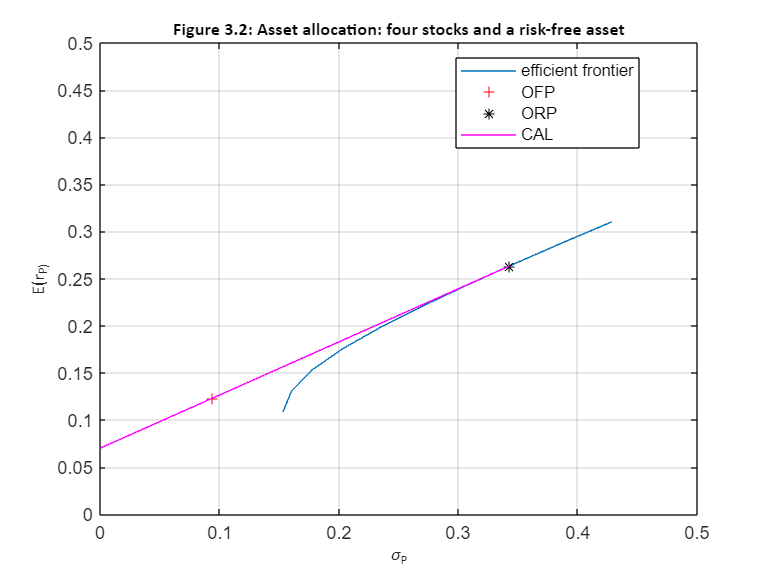


portalloc(port_risk,port_ret,port_wts',rf_rate,br,ra); %Plot the graph.
title({'Figure 3.2: Asset allocation: four stocks and a risk-free asset'},...
    'FontSize',10,'FontName','Calibri'); %Add a title.
ylabel('E(r_P)','FontSize',10,'FontName','Calibri'); %Label the Y axis.
xlabel('\sigma_P','FontSize',10,'FontName','Calibri'); %Label the X axis.
ylim([0 0.5]); %Set limits for the Y axis.
xlim([0 0.5]); %Set limits fr the X axis.
legend('efficient frontier','OFP','ORP','CAL', Location='Best'); %Add a legend.

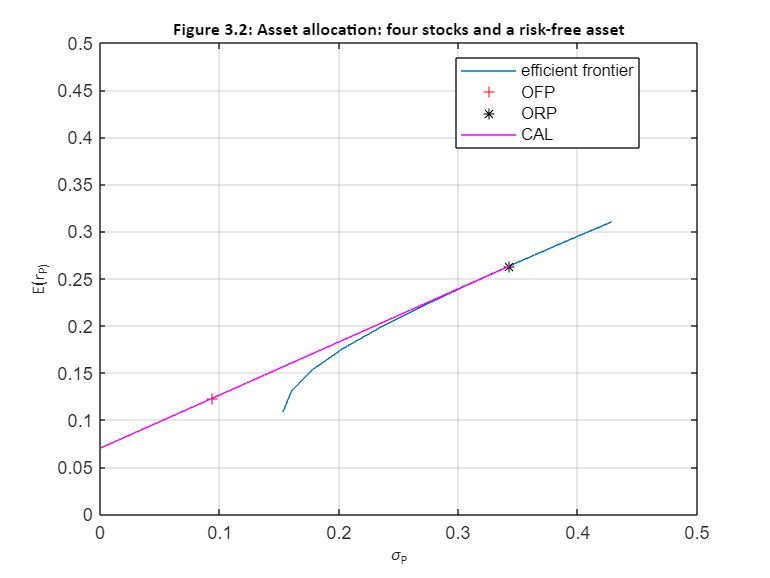

% Saving the current graph
% saveas(gcf,"fig32.jpg"); % Uncomment to save the graph